clear;
if exist('DataSet','dir')
   rmdir('.\DataSet\', 's');
end

mkdir('.\DataSet\');

% 配置
global run_type;
run_type = 'io';
config;

L_recTre = 120


% 产生信号
source;
tag;
global y_sig;
y_sig = y_source;

% % dB 单位信噪比
% y_noise = awgn(y_sig, 50);
% y_sig = y_noise;

global Length;
global Width;

## 房间内的随机点(测试集)

N_inside = 60;
x = Width * rand(1, N_inside);
y = Length * rand(1, N_inside);
% figure; plot(x,y,'r.');

% 计算三个距离
for j=1:2
    [d1, d2, d3] = xy2d(x, y,j, 'inside');
    single_run(d1, d2, d3, false, 'inside', j);
    
end

L_tag is
  列 1 至 15

  101.3104  100.0739  107.8929  108.6809  106.0311  104.0941  101.1317  107.5895  106.1078  110.0836  107.8716  105.7605  111.0900  106.4851  106.4693

  列 16 至 30

  103.2294  111.0122  100.8681  111.7197  101.6292  104.6140  107.2802  101.8559  105.2407  107.7847  101.9738  110.7974  100.7679  105.5324  108.2074

  列 31 至 45

  104.5277  102.7550  107.0907  110.6764  103.9457  112.0188  102.3558   98.6194  110.8481  111.3989  102.3687  105.5906  102.3710   97.8834  111.0367

  列 46 至 60

  105.5550  108.5619  103.3525   99.4010  104.8040  106.5613  102.0889  103.7250  102.2680  101.1399  104.6541  110.3707  105.7267  108.1039  103.9655

delta t is
   1.0e-07 *

  列 1 至 15

    0.0235    0.0107    0.1321    0.1420    0.1140    0.0910    0.0351    0.1397    0.0950    0.1724    0.1349    0.0900    0.1930    0.1028    0.1006

  列 16 至 30

    0.0535    0.1986    0.0396    0.2165    0.0399    0.0840    0.1187    0.0658    0.0859    0.1277    0.0326    0.1865    0.0191

Rate_miss = 0

L_tag is
  列 1 至 15

  101.3804  100.1730  107.9127  108.7094  106.1055  104.1116  101.1620  107.6477  106.1387  110.1019  107.8897  105.8052  111.1085  106.5118  106.5023

  列 16 至 30

  103.2997  111.0257  101.0230  111.7318  101.6594  104.6925  107.3216  101.8750  105.2989  107.8066  102.0208  110.8164  100.8142  105.5495  108.2456

  列 31 至 45

  104.5561  102.7951  107.1329  110.6941  104.0404  112.0308  102.4886   98.8664  110.8814  111.4137  102.3952  105.6282  102.4537   98.2031  111.0561

  列 46 至 60

  105.6065  108.5806  103.4176   99.5463  104.8637  106.5785  102.1252  103.8264  102.3200  101.1934  104.6903  110.3887  105.7499  108.1383  103.9952

delta t is
   1.0e-07 *

  列 1 至 15

    0.0243    0.0117    0.1326    0.1426    0.1148    0.0914    0.0356    0.1404    0.0956    0.1728    0.1353    0.0907    0.1935    0.1034    0.1012

  列 16 至 30

    0.0543    0.1990    0.0409    0.2168    0.0405    0.0849    0.1193    0.0662    0.0867    0.1281    0.0333    0.1869    0.0198

Rate_miss = 0

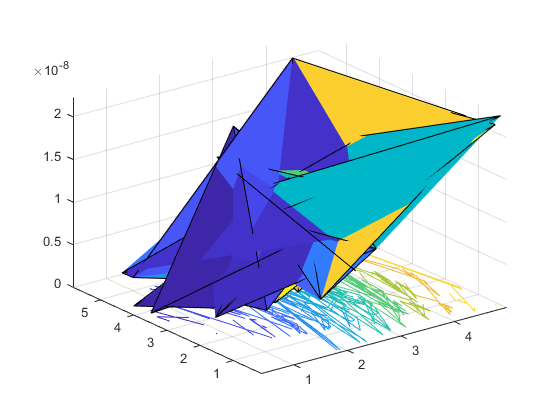

% load('.\DataSet\i_delay_1.mat', "delta_t");
% load('.\DataSet\i_decline_1.mat', "L_tag");
% figure;surfc(reshape(x, 6,10), reshape(y,6,10), reshape(delta_t,6,10));

% figure;surfc(x,y,L_tag);


## 房间周围的随机点

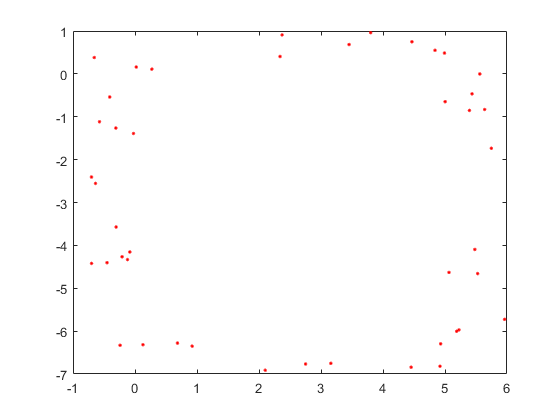

% 1/4 的数量
N_outside = 10;
x0 = rand(4, N_outside);
y0 = rand(4, N_outside);

x0 = [((Width / 2 + 1) * x0(:, 1:floor(N_outside / 2)))   (Width / 2 + x0(:, round(N_outside / 2) : end))];
y0 = [(Length / 2 + y0(:, 1:floor(N_outside / 2)))  ((Length / 2 + 1) * y0(:, round(N_outside / 2): end))];

x0(1,:) = -1 * x0(1, :);
x0(3,:) = -1 * x0(3, :);
y0(3,:) = -1 * y0(3, :);
y0(4,:) = -1 * y0(4, :);

% 坐标原点
x0 = x0 - (-1) * (Width / 2) * ones(size(x0));
y0 = y0 - 1 * (Length / 2) * ones(size(y0));

% 画出散点
figure; plot(x0,y0,'r.');


% 计算三个距离
for j=1:2
    [d1_0, d2_0, d3_0] = xy2d(x0, y0, j, 'outside');
    SinglePoint2(x0, y0, d1_0, d2_0, d3_0, false, 'outside', j);
end

  158.3600  142.3190  166.3560  119.7014  139.2679  120.5711  119.0167  119.0942  120.5924  118.0970  118.9535
  168.6368  169.3051  167.0892  171.4376  171.0451  227.2994  228.4554  224.0701  177.3536  222.5856  227.5664
  146.0424  115.0243  164.9403  144.9506  149.6127  118.6563  118.7431  118.5441  119.0376  118.9402  119.9468
  164.0310  173.1142  172.0123  165.5814  166.8066  162.0738  224.9346  232.5983  218.1988  205.1624  223.6396

delta t is
   1.0e-07 *

    0.1163    0.0470    0.1373    0.0621    0.0463    0.0147    0.0161    0.0229    0.0161    0.0297    0.0184
    0.2443    0.2383    0.1747    0.2009    0.2257    0.2620    0.2424    0.2445    0.2168    0.2346    0.2489
    0.0478    0.0418    0.1228    0.0402    0.0573    0.0121    0.0098    0.0095    0.0158    0.0092    0.0100
    0.2344    0.2496    0.2265    0.1436    0.1611    0.2406    0.2338    0.2772    0.2418    0.2072    0.2250

outside 1


Rate_miss = 0.7273

  158.3895  142.3550  166.3817  119.7180  139.3045  120.6249  119.0485  119.1222  120.6419  118.1197  118.9835
  168.6573  169.3258  167.1135  171.4594  171.0661  227.3200  228.4822  224.0930  177.3791  222.6103  227.5899
  146.6277  115.8857  165.0583  145.8698  150.0432  118.8608  118.9311  118.7460  119.2292  119.1114  120.0516
  164.0588  173.1414  172.0451  165.6604  166.8687  162.0990  224.9767  232.6367  218.2485  205.2117  223.6801

delta t is
   1.0e-07 *

    0.1166    0.0474    0.1376    0.0626    0.0468    0.0154    0.0167    0.0235    0.0168    0.0302    0.0190
    0.2447    0.2386    0.1750    0.2012    0.2260    0.2623    0.2427    0.2448    0.2172    0.2350    0.2493
    0.0503    0.0448    0.1239    0.0433    0.0594    0.0136    0.0112    0.0110    0.0172    0.0105    0.0110
    0.2349    0.2501    0.2271    0.1445    0.1619    0.2411    0.2343    0.2777    0.2423    0.2077    0.2254

outside 2


Rate_miss = 0.7500

## 上下房间

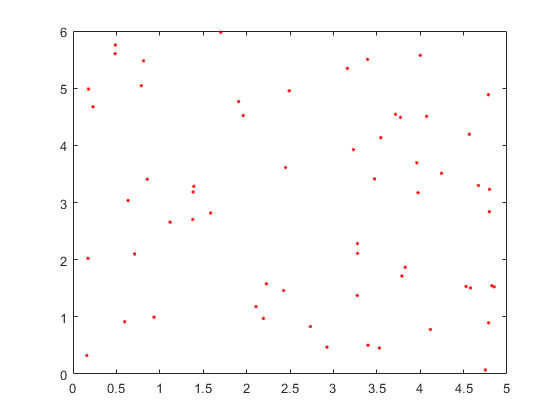

N_up = 20;
x_u = Width * rand(1, N_up);
y_u = Length * rand(1, N_up);
figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1_u, d2_u, d3_u] = xy2d(x, y,j, 'up');
    single_run(d1_u, d2_u, d3_u, false, 'up', j);
end

L_tag is
  列 1 至 16

  128.8676  130.0111  120.2195  130.0718  126.6644  116.5917  121.4608  124.9115  130.9797  130.7767  118.4361  130.8568  130.9230  123.7645  129.3012  119.5548

  列 17 至 32

  122.6165  130.1514  128.3320  130.4698  126.3796  117.3406  129.0703  130.1588  127.4928  127.9150  127.8842  122.5644  126.3663  120.4673  127.7626  111.2116

  列 33 至 48

  121.4490  118.1360  116.6702  129.2536  126.9498  121.8383  131.4677  118.8666  122.9085  122.3422  127.9897  128.3104  117.7427  124.0869  123.1305  126.3336

  列 49 至 60

  127.2753  128.0266  121.3454  127.3171  126.4919  117.9593  116.1271  124.3017  130.4834  121.9985  125.7910  120.8004

delta t is
   1.0e-07 *

  列 1 至 16

    0.1497    0.1730    0.0092    0.1725    0.1185    0.0293    0.0252    0.0925    0.1969    0.1892    0.0222    0.1910    0.1938    0.0688    0.1657    0.0101

  列 17 至 32

    0.0589    0.1761    0.1358    0.1790    0.1020    0.0131    0.1499    0.1723    0.1333    0.1313    0.1316    0.0516

Rate_miss = 0.8333

L_tag is
  列 1 至 16

  128.8257  129.9912  120.1378  130.0388  126.5916  115.9041  121.3801  124.8880  130.9632  130.7580  118.0976  130.8383  130.8900  123.7344  129.2530  119.5052

  列 17 至 32

  122.5876  130.1317  128.2943  130.4455  126.3488  116.9208  129.0375  130.1313  127.4276  127.8905  127.8351  122.4454  126.3339  120.3686  127.7439  111.1867

  列 33 至 48

  121.3722  117.8318  116.0331  129.2353  126.9079  121.7774  131.4537  118.8173  122.8818  122.2062  127.9644  128.2770  117.7120  124.0215  123.0980  126.2809

  列 49 至 60

  127.2266  127.9793  121.2851  127.2978  126.4669  117.5096  116.0967  124.2011  130.4573  121.7814  125.7704  120.7386

delta t is
   1.0e-07 *

  列 1 至 16

    0.1490    0.1725    0.0082    0.1719    0.1175    0.0264    0.0242    0.0920    0.1965    0.1887    0.0201    0.1906    0.1932    0.0682    0.1649    0.0093

  列 17 至 32

    0.0583    0.1756    0.1351    0.1785    0.1013    0.0108    0.1493    0.1717    0.1325    0.1307    0.1308    0.0504

Rate_miss = 0.8333


N_dn = 20;
x_d = Width * rand(1, N_dn);
y_d = Length * rand(1, N_dn);
figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1_d, d2_d, d3_d] = xy2d(x, y,j, 'down');
    single_run(d1_d, d2_d, d3_d, false, 'down', j);
end

L_tag is
  列 1 至 16

  132.7666  133.6820  128.2817  133.5348  131.6153  128.8787  128.7668  131.2183  134.4012  134.1752  128.5727  134.2306  134.1349  130.4396  133.1428  128.5465

  列 17 至 32

  130.1854  133.7750  132.4023  133.8367  131.4295  128.3210  132.8750  133.6013  132.0874  132.3804  132.1674  129.4949  131.3801  128.3524  132.6503  129.4506

  列 33 至 48

  128.7689  128.2187  128.7592  133.3667  131.5669  129.0118  134.8450  128.4137  130.4136  129.5091  132.3901  132.4058  129.2090  129.9993  130.1270  131.2164

  列 49 至 60

  131.7727  132.2477  128.8399  132.4155  131.7092  128.8344  129.0910  130.3781  133.8243  130.0236  131.7444  128.6380

delta t is
   1.0e-07 *

  列 1 至 16

    0.2364    0.2575    0.1342    0.2546    0.2139    0.1635    0.1442    0.2004    0.2782    0.2706    0.1512    0.2721    0.2725    0.1806    0.2505    0.1398

  列 17 至 32

    0.1764    0.2600    0.2250    0.2605    0.2010    0.1462    0.2363    0.2546    0.2254    0.2243    0.2222    0.1645

Rate_miss = 1

L_tag is
  列 1 至 16

  132.8659  133.7421  128.4213  133.6204  131.7480  129.1027  128.9057  131.2862  134.4533  134.2325  128.7793  134.2875  134.2204  130.5203  133.2505  128.6559

  列 17 至 32

  130.2638  133.8344  132.4954  133.9062  131.5113  128.5339  132.9604  133.6771  132.2134  132.4504  132.2760  129.6562  131.4647  128.5031  132.7076  129.5213

  列 33 至 48

  128.9048  128.4219  128.9818  133.4229  131.6663  129.1337  134.8907  128.5227  130.4878  129.6775  132.4615  132.4921  129.2907  130.1255  130.2117  131.3294

  列 49 至 60

  131.8809  132.3543  128.9611  132.4742  131.7801  129.0491  129.1721  130.5299  133.8974  130.2140  131.8060  128.7608

delta t is
   1.0e-07 *

  列 1 至 16

    0.2386    0.2592    0.1368    0.2567    0.2164    0.1668    0.1468    0.2022    0.2798    0.2723    0.1543    0.2738    0.2746    0.1826    0.2528    0.1421

  列 17 至 32

    0.1784    0.2617    0.2271    0.2623    0.2030    0.1494    0.2383    0.2565    0.2279    0.2261    0.2245    0.1673

Rate_miss = 1

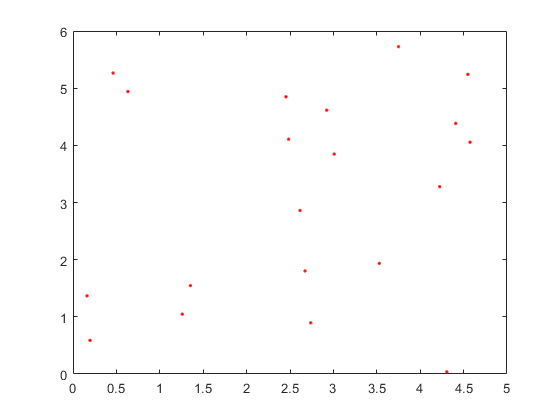

% 画出散点
% figure; plot(x_u,y_u,'r.');

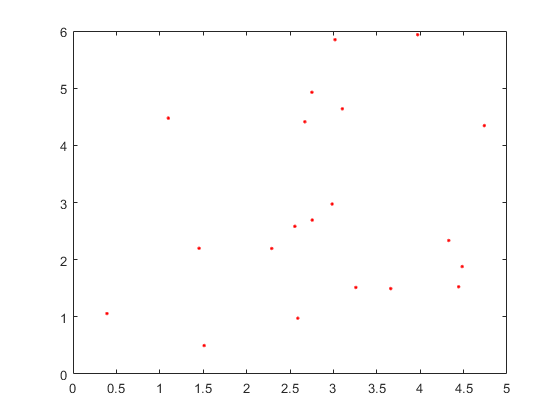

% figure; plot(x_d,y_d,'r.');

## 保存数据集的信息

% 保存样本点
filename = '.\DataSet\sample.mat'

filename = '.\DataSet\sample.mat'

save(filename, 'N_inside', 'N_outside', 'N_up', 'N_dn',...
    'x', 'y', 'd1', 'd2', 'd3', ...
    'x0', 'y0', 'd1_0', 'd2_0', 'd3_0', ...
    'x_u', 'y_u', 'd1_u', 'd2_u', 'd3_u', ...
    'x_d', 'y_d', 'd1_d', 'd2_d', 'd3_d');

## 数据预处理

% [] = preproc(filename, i, draw, isBeacon)
load('.\DataSet\sample.mat', "N_inside", "N_outside");
load('.\DataSet\sample.mat', "N_up", "N_dn");

for i=1: N_inside
    preproc('i_sig_rx', i, false, 'inside');
end

% outside
for i=1: 4 * N_outside
    preproc('o_sig_rx', i, false, 'outside');
end

% up
for i=1: N_up
    preproc('u_sig_rx', i, false, 'up');
end

% down
for i=1: N_dn
    preproc('d_sig_rx', i, false, 'down');
end